clf

mm_to_m = 1/1000;
S_thickness = 5.4*mm_to_m;
J_thickness = 5.4*mm_to_m;
width = 40*mm_to_m;

constants = containers.Map;
constants('youngs_mod') = 29*10^9;%5*10^9%25*10^9 %29*10^9;%250*10^9;
constants('shear_mod') = 10*10^9;%1.9*10^9%10*10^9;
constants('shape_factor') = 6/5;

forces = containers.Map();
% F = 1000; %/(360);
F = 1400; %/(360);
Fa = pi; 
V = F*sin(Fa); 
H = F*cos(Fa);
forces('f') = [V; H];

s1 = containers.Map;
s1('thickness') = S_thickness;
s1('length') = (125)*mm_to_m;
s1('width') = width;
s1('beam_angle') = -10*(pi/180); % rad
s1('couple') = 0; % init
s1('boundary_angle') = 0;
s1('boundary_defV') = 0;
s1('boundary_defH') = 0;
straight1 = Straight(constants, s1);


% FOR A CURVED SECTION, THE  start_angle IS THE LOADED END
c1 = containers.Map();
c1('length') = 125*mm_to_m;
c1('height') = 30*mm_to_m;
c1('thickness') = J_thickness;
c1('width') = width;
c1('chord') = sqrt(c1('height')^2+c1('length')^2);

% if radius is unknown
% approximately true if length is greater than height (otherwise sweep
% angle does not hold!!
c1('sweep_angle') = 2*atan(c1('height')/c1('length'));
c1('radius') = 0.5*c1('chord')/asin(0.5*c1('sweep_angle'));

% if radius is known
% c1('radius') = 544.5*mm_to_m;
% c1('sweep_angle') = 2*asin(0.5*c1('chord')/c1('radius'));

c1('start_angle') = -pi/2;
c1('end_angle') = -pi/2+c1('sweep_angle');
c1('boundary_angle') = 0;
c1('boundary_defV') = 0;
c1('boundary_defH') = 0;
c1('couple') = 0; % init
curved = Curved(constants, c1);

% FOR A CURVED SECTION, THE  start_angle IS THE LOADED END
c2 = containers.Map();
c2('length') = 57*mm_to_m;
c2('height') = 82*mm_to_m;
c2('thickness') = J_thickness;
c2('width') = width;
c2('chord') = sqrt(c2('height')^2+c2('length')^2);

% if radius is unknown
% c2('sweep_angle') = 2*atan(c2('height')/c2('length'));
% c2('radius') = 0.5*c2('chord')/asin(0.5*c2('sweep_angle'));

% if radius is known
% c2('radius') = 400*mm_to_m;
c2('radius') = 87.4824*mm_to_m;
c2('sweep_angle') = 2*asin(0.5*c2('chord')/c2('radius'));

% c2('start_angle') = -c2('sweep_angle');
% c2('end_angle') = -2*c2('sweep_angle');
% c2('start_angle') = 0.482287;
% c2('end_angle') = 0.732602; 
c2('start_angle') = 0;
% c2('end_angle') = -1.21489;
c2('end_angle') = pi/2;
c2('boundary_angle') = 0;
c2('boundary_defV') = 0;
c2('boundary_defH') = 0;
c2('couple') = 0; % init
curved2 = Curved(constants, c2);

% FOR A CURVED SECTION, THE  start_angle IS THE LOADED END
c3 = containers.Map();
c3('length') = 57*mm_to_m;
c3('height') = 82*mm_to_m;
c3('thickness') = J_thickness;
c3('width') = width;
c3('chord') = sqrt(c3('height')^2+c3('length')^2);

c3('radius') = 87.4824*mm_to_m;
c3('sweep_angle') = 2*asin(0.5*c3('chord')/c3('radius'));

% c2('start_angle') = -c2('sweep_angle');
% c2('end_angle') = -2*c2('sweep_angle');
% c2('start_angle') = 0.482287;
% c2('end_angle') = 0.732602; 
c3('start_angle') = 0;
% c2('end_angle') = -1.21489;
c3('end_angle') = -pi/2;
c3('boundary_angle') = 0;
c3('boundary_defV') = 0;
c3('boundary_defH') = 0;
c3('couple') = 0; % init
curved3 = Curved(constants, c3);

sections = containers.Map();
% sections('1') = straight1;
% sections('1') = curved;
sections('2') = curved2;
sections('1') = curved3;

[x_base, y_base, x_deformed, y_deformed, moment, ang, strain_e] = stitch(sections, forces);

in function
    0.0875

   -0.0875

  122.4754



$$ans = 0.0$$

$$Mo = 122.47535999999999489773472305387$$

in class
    0.0875

    0.0875

in function
     0

     0

     0



$$ans = 0.0$$

$$Mo = 0.0$$

in class
    0.0875

   -0.0875



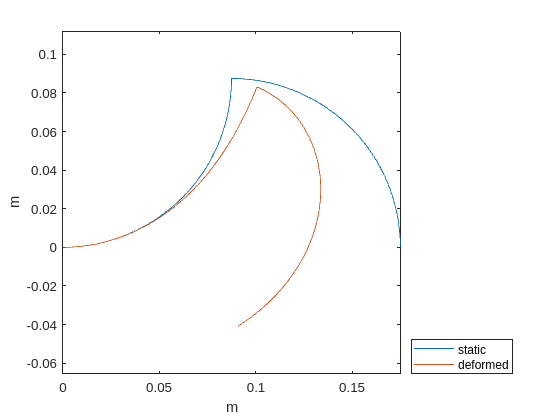

title('deflection')
plot(x_base, y_base)
hold on
plot(x_deformed, y_deformed)
xlabel('m')
ylabel('m')
legend('static', 'deformed', location='southeastoutside')
axis('equal')
hold off

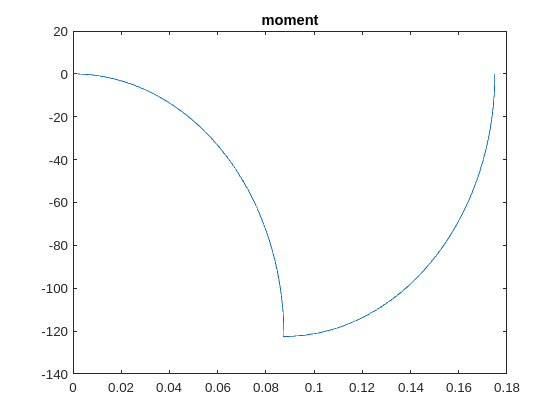

% plot(x_base, strain_e)
% title('strain E')
plot(x_base, moment)
title('moment') 

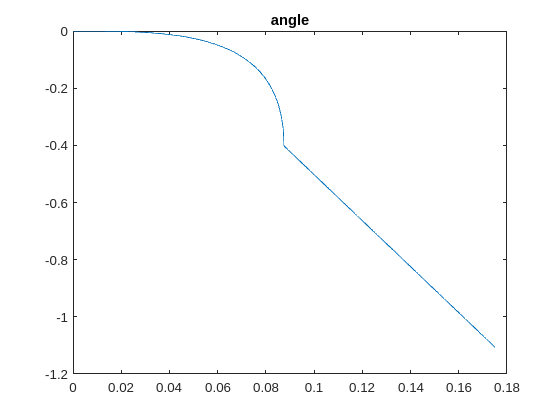

plot(x_base, ang)
title('angle')

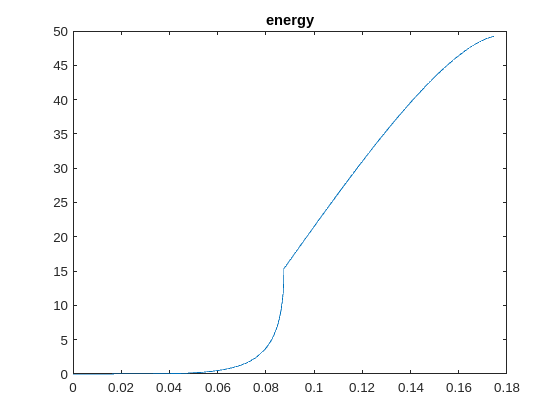

plot(x_base, strain_e)
title('energy')

function [x_base, y_base, x_deformed, y_deformed, M, ang, strain_e] = stitch(sections, forces)
    f = forces('f'); % is in the form [V; H]
    
    v_offset = 0; % buffer to be overwritten for each loop
    h_offset = 0;
    a_offset = 0;
    
    M = [];
    strain_e = [];
    ang = [];
    x_base = []; % build undeformed x state of beam for plotting
    y_base = []; % build undeformed y state of beam for plotting

    x_offset = 0;
    xdef_offset = 0;
    y_offset = 0;
    ydef_offset = 0;

    x_deformed = []; % absolute x position of deformed beam
    y_deformed = []; % absolute y position of deformed beam

    angle_offset = 0;
    energy_offset= 0;

    for s = 1:size(sections)
        sec = sections(string(s)); % key in Map indicates order of sections
        height = 0; % sum as we iterate through beam sections to find moment
        length = 0;
        % sum remaining distance to point of load for moment calcualtion
        for s_other = s+1:size(sections)
            height = height + sections(string(s_other)).height;
            length = length + sections(string(s_other)).length;
        end
        disp('in function')
        disp(length)
        disp(height)

        if (sec.start_angle > sec.end_angle) % || (obj.start_angle < 0 || obj.end_angle < 0)
            moment = cross([-height -length 0], [-f(1); -f(2); 0]); % +length
        else
            moment = cross([-height -length 0], [f(1); f(2); 0]); % +length
        end

%         moment = cross([-height -length 0], [f(1); f(2); 0]); % +length

        sec.couple = moment(3);
        disp(moment(3))
        sec.ba = a_offset;
%         sec.ba = 0;
        sec.bV = v_offset;
        sec.bH = h_offset;
%         
        [h_base, v_base, h_def, v_def, m, angle, energy] = sec.def(forces, 'linspace');
        h_base = h_base - h_base(1);
        v_base = v_base - v_base(1);
        h_def = h_def - h_def(1);
        v_def = v_def - v_def(1);

        M = [M m];
        strain_e = [strain_e energy+energy_offset];
        ang = [ang angle+angle_offset];

        x_base = [x_base h_base+x_offset];
        y_base = [y_base v_base+y_offset];

        x_deformed = [x_deformed h_def+xdef_offset]; % absolute x position of deformed beam
        y_deformed = [y_deformed v_def+ydef_offset]; % absolute y position of deformed beam

        x_offset = x_offset + h_base(end);
        y_offset = y_offset + v_base(end);
        xdef_offset = xdef_offset + h_def(end);
        ydef_offset = ydef_offset + v_def(end);

        angle_offset = angle(end);
        energy_offset = strain_e(end);

%         a_offset = a_offset - angle(end);
        a_offset = a_offset + angle(end);
%         v_offset = v_def(end) - h_base(end);
%         h_offset = h_def(end) - v_base(end);    
        v_offset = v_def(end) - v_base(end);
        h_offset = h_def(end) - h_base(end);

    end
end
































%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [x_base, y_base, x_deformed, y_deformed, M, ang, strain_e] = stitch_shooting(sections, forces)
    f = forces('f'); % is in the form [V; H]
    
    v_offset = 0; % buffer to be overwritten for each loop
    h_offset = 0;
    a_offset = 0;
    
    M = [];
    strain_e = [];
    ang = [];
    x_base = []; % build undeformed x state of beam for plotting
    y_base = []; % build undeformed y state of beam for plotting

    x_offset = 0;
    xdef_offset = 0;
    y_offset = 0;
    ydef_offset = 0;

    x_deformed = []; % absolute x position of deformed beam
    y_deformed = []; % absolute y position of deformed beam

    angle_offset = 0;

    for s = 1:size(sections)
        while true
            sec = sections(string(s)); % key in Map indicates order of sections
            height = 0; % sum as we iterate through beam sections to find moment
            length = 0;
            % sum remaining distance to point of load for moment calcualtion
            for s_other = s+1:size(sections)
                height = height + sections(string(s_other)).height;
                length = length + sections(string(s_other)).length;
            end

            moment = cross([height -length 0], [f(1); f(2); 0]);
            sec.couple = moment(3);
            sec.ba = a_offset;
            sec.bV = v_offset;
            sec.bH = h_offset;
    %         
            [h_base, v_base, h_def, v_def, m, angle, energy] = sec.def(forces, 'linspace');
%             h_base = h_base - h_base(1);
%             v_base = v_base - v_base(1);
%             h_def = h_def - h_def(1);
%             v_def = v_def - v_def(1);
    
            M = [M m];
            strain_e = [strain_e energy];
            ang = [ang angle+angle_offset];
    
            x_base = [x_base h_base+x_offset];
            y_base = [y_base v_base+y_offset];
    
            x_deformed = [x_deformed h_def+xdef_offset]; % absolute x position of deformed beam
            y_deformed = [y_deformed v_def+ydef_offset]; % absolute y position of deformed beam
    
            x_offset = x_offset + h_base(end);
            y_offset = y_offset + v_base(end);
            xdef_offset = xdef_offset + h_def(end);
            ydef_offset = ydef_offset + v_def(end);
    
            angle_offset = angle(end);
    
    %         a_offset = a_offset - angle(end);
            a_offset = a_offset + angle(end);
    %         v_offset = v_def(end) - h_base(end);
    %         h_offset = h_def(end) - v_base(end);    
            v_offset = v_def(end) - v_base(end);
            h_offset = h_def(end) - h_base(end);
        end

    end
end
